# Quantify the effect of the complement track(s) on the model

Up to now, all the trained models are for 3 channels of input. The strategy towards 1 or 2 channels input is to complement the missing channel(s).

This live code is to quantify the effect of this strategy, how this forging method causes inaccuracy and to what extent the 3 channels correlate.

Also, some add-on features related to this for the detectBlinks function might be needed:

- Specified single-channel model.  

- Detect the missing channel if the user does not specify, generate the missing one.

- Warning of the lower bound of the sampling frequency. Lower than a range(need further testing) may cause the result unreliable. 

## Load the data and model

modelName = 'TCNOC';
model = load(['Models\trainedModels\' modelName 'net.mat']).net;
samplingRate = 512;
path = 'DataSet\OpeningClosing';
[~,XTest,~,YTest] = creatOCdataset(1);

## The acc for 1/2/3 channels data

#### Full 3 channels

YPred = classify(model, XTest, "MiniBatchSize",1);
[accuracy,TP,FP,FN] = testOC(YTest,YPred)

#### Faked Fz according to Fp1 and Fp2

Fz = {};

accuracy = 0.9409

TP = 2124

FP = 286

FN = 270

for i = 1:numel(XTest)
    Fz{end+1} = XTest{i}(3,:);
    XTest{i} = [XTest{i}(1,:);XTest{i}(2,:);mean(XTest{i},1)/2];
end
YPred = classify(model, XTest, "MiniBatchSize",1);
[accuracy,TP,FP,FN] = testOC(YTest,YPred)

#### Only Fp1 input

for i = 1:numel(XTest)

accuracy = 0.9394

TP = 2123

FP = 264

FN = 285

    XTest{i} = [XTest{i}(1,:);XTest{i}(1,:);XTest{i}(1,:)/2];
end
YPred = classify(model, XTest, "MiniBatchSize",1);
[accuracy,TP,FP,FN] = testOC(YTest,YPred)

#### Only Fz input

for i = 1:numel(XTest)

accuracy = 0.9329

TP = 2098

FP = 300

FN = 339

    Fz{i} = [Fz{i}*2;Fz{i}*2;Fz{i}];
end
YPred = classify(model, Fz, "MiniBatchSize",1);
[accuracy,TP,FP,FN] = testOC(YTest,YPred)

accuracy = 0.9267

TP = 1944

FP = 186

FN = 627

The size of this test case is 2417. The result shows that the generated data does cause worse performance but is not too significant.

## Correlation between channels

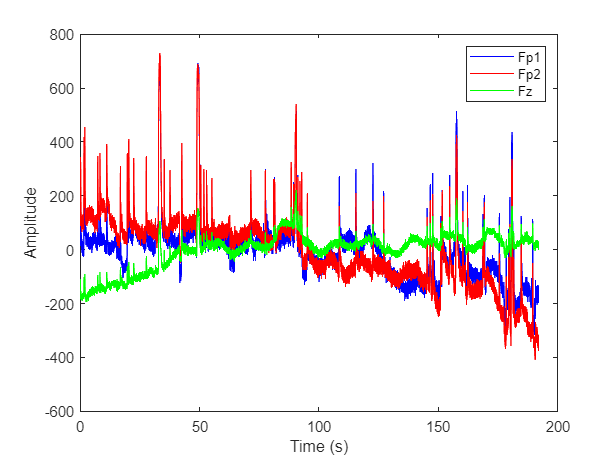

% reload data
HC_1 = table2array(importfile("EEG_Blink\RawData\HC_1.csv"));
% % normalize to the range [0, 1]
% HC_1 = (HC_1 - min(HC_1)) ./ (max(HC_1) - min(HC_1));
HC_1 = HC_1 - mean(HC_1);
time = (1:length(HC_1)) / samplingRate;
figure;
plot(time, HC_1(:, 1), 'b', 'DisplayName', 'Fp1'); hold on;
plot(time, HC_1(:, 2), 'r', 'DisplayName', 'Fp2');
plot(time, HC_1(:, 3), 'g', 'DisplayName', 'Fz');
xlabel('Time (s)');
ylabel('Amplitude');
legend('show'); hold off;
% Pearson correlation matrix
HC_1 = table2array(importfile("EEG_Blink\RawData\HC_1.csv"));
pearsonCorrelation = corrcoef(HC_1)

Seems affecetd by drift.

for i = 1:size(HC_1, 2)    
    pf = polyfit([1, size(HC_1, 1)], [HC_1(1, i), HC_1(end, i)],1);

pearsonCorrelation =     1.0000    0.8961    0.0738
    0.8961    1.0000   -0.1807
    0.0738   -0.1807    1.0000


    HC_1(:,i) = HC_1(:,i) - (pf(1)*([1: size(HC_1, 1)]')+pf(2));
end
pearsonCorrelation = corrcoef(HC_1)

Fp1 and Fp2 are correlated, and Fz is stand out. 

## Try to get resonable parmters

I was thinking about setting up a gird search for getting the best scale for generating Fz when it is missing, the former factor is 2, which was got by the naked eye and intuition. I doubt that taking the mean of Fp1 and Fp2 and then multiplying by a factor might not be the best way. Although the models tolerate this complement method, this kind of method is trying to manually overfit the current dataset.

pearsonCorrelation =     1.0000    0.8419    0.6431
    0.8419    1.0000    0.5494
    0.6431    0.5494    1.0000
